clc;
clear;
close all;

%% ── CONFIGURATION ────────────────────────────────────────────────────────
datasetPath   = 'C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset';
modelSavePath = fullfile(datasetPath, 'trained_lung_model.mat');
IMG_SIZE      = [224 224];
MAX_EPOCHS    = 15;
MINI_BATCH    = 16;

%% ── OUTPUT FOLDERS ───────────────────────────────────────────────────────
outputRoot      = fullfile(datasetPath, 'Results');          % master output folder
gridOutputDir   = fullfile(outputRoot,  'Grid_Windows');     % figure grid images
benignDir       = fullfile(outputRoot,  'Benign');           % individual benign
malignantDir    = fullfile(outputRoot,  'Malignant');        % individual malignant
wrongDir        = fullfile(outputRoot,  'Wrong_Predictions');% misclassified

% Create all folders if they don't exist
for d = {outputRoot, gridOutputDir, benignDir, malignantDir, wrongDir}
    if ~exist(d{1}, 'dir'), mkdir(d{1}); end
end

fprintf('📁 Output will be saved to:\n   %s\n\n', outputRoot);

📁 Output will be saved to:
   C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results




%% ── STEP 1 : Load Dataset ────────────────────────────────────────────────
imds = imageDatastore(datasetPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource',       'foldernames');

imds.ReadFcn = @(f) preprocessImage(f, IMG_SIZE);

labelCount = countEachLabel(imds);
disp('=== Dataset Label Counts ===');

=== Dataset Label Counts ===


disp(labelCount);

             Label             Count
    _______________________    _____

    Benign cases                120 
    Lung Cancer Dataset           2 
    Normal cases                631 
    adenocarcinoma              337 
    large cell carcinoma        187 
    squamous cell carcinoma     260 



numClasses = numel(categories(imds.Labels));

%% ── STEP 2 : Fixed Split ─────────────────────────────────────────────────
rng(42);
[trainData, testData] = splitEachLabel(imds, 0.7, 'randomized');

if numel(trainData.Files) == 0 || numel(testData.Files) == 0
    error('Dataset too small. Add more images per class.');
end

%% ── STEP 3 : Load OR Train ───────────────────────────────────────────────
if isfile(modelSavePath)
    fprintf('✅ Model found. Loading — skipping training.\n');
    load(modelSavePath, 'net');
else
    fprintf('🚀 Training for the FIRST TIME only...\n');

    augmenter = imageDataAugmenter( ...
        'RandXReflection',  true, ...
        'RandYReflection',  true, ...
        'RandRotation',     [-20 20], ...
        'RandXTranslation', [-15 15], ...
        'RandYTranslation', [-15 15], ...
        'RandXScale',       [0.85 1.15], ...
        'RandYScale',       [0.85 1.15]);

    augTrain   = augmentedImageDatastore(IMG_SIZE, trainData, 'DataAugmentation', augmenter);
    augValTemp = augmentedImageDatastore(IMG_SIZE, testData);

    baseNet = googlenet;
    lgraph  = layerGraph(baseNet);

    newFC   = fullyConnectedLayer(numClasses, ...
                  'Name', 'new_fc', ...
                  'WeightLearnRateFactor', 10, ...
                  'BiasLearnRateFactor',   10);
    newSoft = softmaxLayer('Name', 'new_softmax');
    newOut  = classificationLayer('Name', 'new_classoutput');

    lgraph = replaceLayer(lgraph, 'loss3-classifier', newFC);
    lgraph = replaceLayer(lgraph, 'prob',             newSoft);
    lgraph = replaceLayer(lgraph, 'output',           newOut);

    options = trainingOptions('adam', ...
        'MaxEpochs',           MAX_EPOCHS, ...
        'MiniBatchSize',       MINI_BATCH, ...
        'InitialLearnRate',    1e-4, ...
        'LearnRateSchedule',   'piecewise', ...
        'LearnRateDropFactor', 0.5, ...
        'LearnRateDropPeriod', 5, ...
        'Shuffle',             'every-epoch', ...
        'ValidationData',      augValTemp, ...
        'ValidationFrequency', 10, ...
        'Verbose',             true, ...
        'Plots',               'training-progress');

    net = trainNetwork(augTrain, lgraph, options);
    save(modelSavePath, 'net');
    fprintf('💾 Model saved.\n');
end

✅ Model found. Loading — skipping training.



%% ── STEP 4 : Classify ALL Test Images ────────────────────────────────────
fprintf('\n🔍 Classifying %d test images...\n', numel(testData.Files));


🔍 Classifying 461 test images...



augTest         = augmentedImageDatastore(IMG_SIZE, testData);
predictedLabels = classify(net, augTest);
actualLabels    = testData.Labels;
[~, allScores]  = classify(net, augTest);

accuracy = sum(predictedLabels == actualLabels) / numel(actualLabels) * 100;
fprintf('\n======================================\n');

fprintf('  Total Test Images : %d\n',    numel(testData.Files));

  Total Test Images : 461


fprintf('  Model Accuracy    : %.2f%%\n', accuracy);

  Model Accuracy    : 64.43%


fprintf('======================================\n\n');


%% ── STEP 5 : Confusion Matrix — Display + Save ───────────────────────────
figCM = figure('Name', 'Confusion Matrix', 'NumberTitle', 'off');
cm = confusionchart(actualLabels, predictedLabels);
cm.Title         = sprintf('Lung Cancer Classification  |  Accuracy: %.2f%%', accuracy);
cm.RowSummary    = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
drawnow;

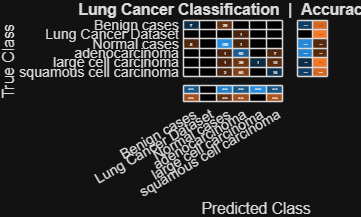


% ── SAVE confusion matrix ─────────────────────────────────────────────────
cmSavePath = fullfile(outputRoot, 'Confusion_Matrix.png');
exportgraphics(figCM, cmSavePath, 'Resolution', 150);

fprintf('💾 Saved: %s\n', cmSavePath);

💾 Saved: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Confusion_Matrix.png



%% ── STEP 6 : Per-Class Metrics ───────────────────────────────────────────
classNames = categories(actualLabels);
fprintf('\n%-20s  %-12s  %-12s  %-12s\n', 'Class','Precision','Recall','F1-Score');


Class                 Precision     Recall        F1-Score    


fprintf('%s\n', repmat('-',1,60));

------------------------------------------------------------


for i = 1:numClasses
    tp   = sum(predictedLabels == classNames{i} & actualLabels == classNames{i});
    fp   = sum(predictedLabels == classNames{i} & actualLabels ~= classNames{i});
    fn   = sum(predictedLabels ~= classNames{i} & actualLabels == classNames{i});
    prec = tp / max(tp+fp, 1);
    rec  = tp / max(tp+fn, 1);
    f1   = 2*prec*rec / max(prec+rec, 1e-6);
    fprintf('%-20s  %-12.2f  %-12.2f  %-12.2f\n', classNames{i}, prec, rec, f1);
end

Benign cases          0.47          0.19          0.27        
Lung Cancer Dataset   0.00          0.00          0.00        
Normal cases          0.85          0.95          0.90        
adenocarcinoma        0.48          0.92          0.63        
large cell carcinoma  1.00          0.02          0.04        
squamous cell carcinoma  0.42          0.21          0.28        



%% ── STEP 7 : Grid Windows — Display + Save ───────────────────────────────
COLS       = 5;
ROWS       = 4;
perFig     = COLS * ROWS;
totalImages = numel(testData.Files);
numFigures  = ceil(totalImages / perFig);

fprintf('\n📊 Displaying + saving all %d images across %d window(s)...\n', ...
        totalImages, numFigures);


📊 Displaying + saving all 461 images across 24 window(s)...


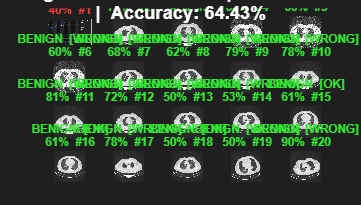

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_01.png


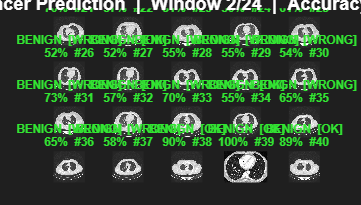

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_02.png


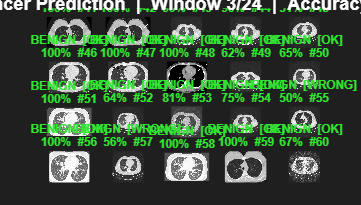

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_03.png


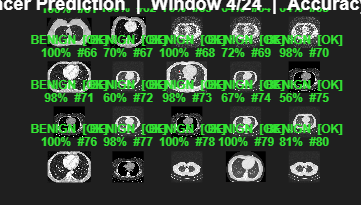

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_04.png


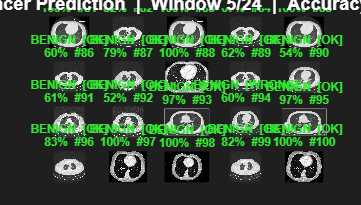

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_05.png


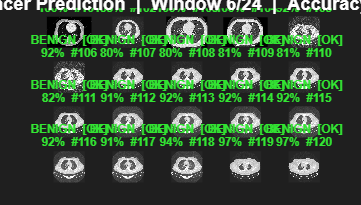

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_06.png


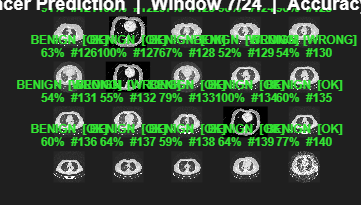

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_07.png


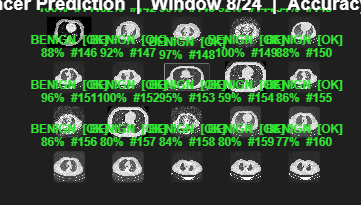

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_08.png


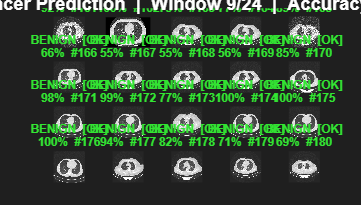

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_09.png


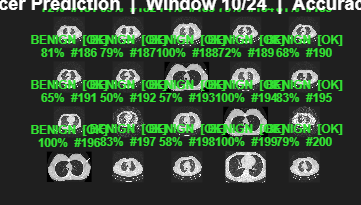

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_10.png


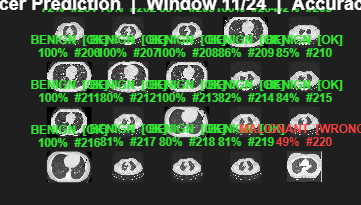

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_11.png


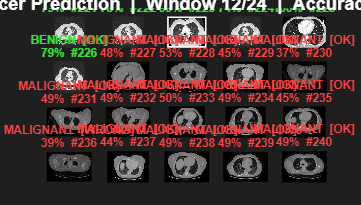

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_12.png


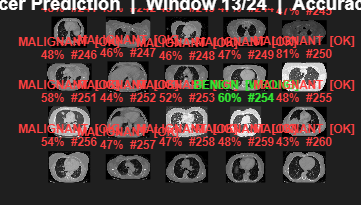

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_13.png


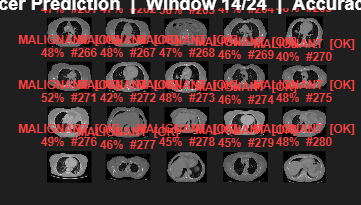

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_14.png


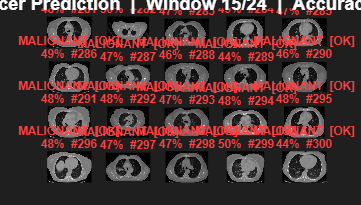

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_15.png


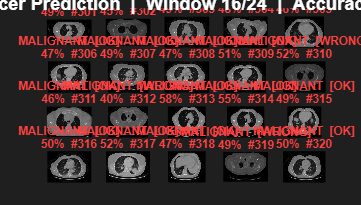

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_16.png


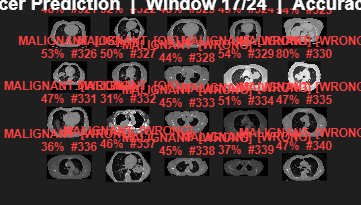

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_17.png


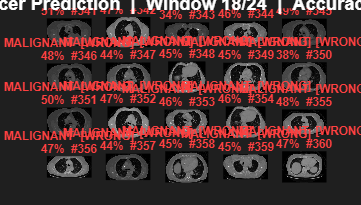

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_18.png


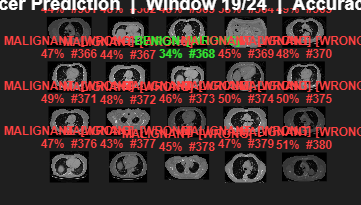

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_19.png


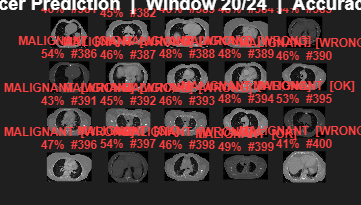

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_20.png


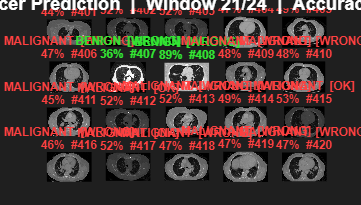

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_21.png


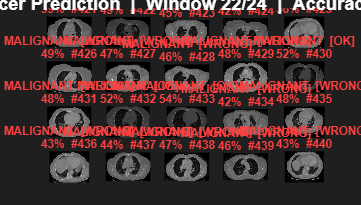

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_22.png


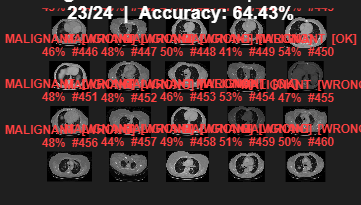

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_23.png


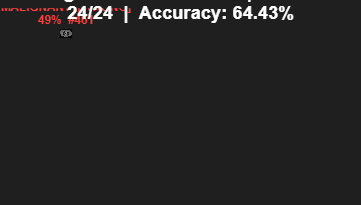

💾 Saved grid: C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Grid_Windows\Grid_Window_24.png



for figIdx = 1:numFigures
    startIdx   = (figIdx-1)*perFig + 1;
    endIdx     = min(figIdx*perFig, totalImages);
    batchCount = endIdx - startIdx + 1;

    figGrid = figure('Name', sprintf('Predictions — Window %d of %d', figIdx, numFigures), ...
                     'NumberTitle', 'off', ...
                     'Color',       [0.12 0.12 0.12], ...
                     'Units',       'normalized', ...
                     'Position',    [0.01 0.05 0.97 0.88]);

    for k = 1:batchCount
        imgIdx = startIdx + k - 1;

        rawImg = imread(testData.Files{imgIdx});
        if size(rawImg,3) == 1,  rawImg = cat(3,rawImg,rawImg,rawImg); end
        if size(rawImg,3) == 4,  rawImg = rawImg(:,:,1:3);             end

        predLabel  = char(predictedLabels(imgIdx));
        trueLabel  = char(actualLabels(imgIdx));
        confidence = max(allScores(imgIdx,:)) * 100;

        predLow = lower(predLabel);
        if contains(predLow,'benign') || contains(predLow,'normal')
            tumorTag   = 'BENIGN';
            titleColor = [0.2 0.9 0.2];
        elseif contains(predLow,'malignant') || contains(predLow,'cancer') || ...
               contains(predLow,'adeno')     || contains(predLow,'squamous') || ...
               contains(predLow,'large')
            tumorTag   = 'MALIGNANT';
            titleColor = [1.0 0.25 0.25];
        else
            tumorTag   = upper(predLabel);
            titleColor = [0.4 0.6 1.0];
        end

        if strcmp(predLabel, trueLabel)
            verdict     = 'OK';
            borderColor = [0.1 0.8 0.1];
        else
            verdict     = 'WRONG';
            borderColor = [1.0 0.2 0.2];
        end

        subplot(ROWS, COLS, k);
        imshow(rawImg);
        title(sprintf('%s  [%s]\n%.0f%%  #%d', tumorTag, verdict, confidence, imgIdx), ...
              'Color', titleColor, 'FontSize', 7, 'FontWeight', 'bold');
        ax = gca;
        ax.XColor    = borderColor;
        ax.YColor    = borderColor;
        ax.LineWidth = 2.5;
    end

    annotation('textbox', [0 0.96 1 0.04], ...
        'String',  sprintf('Lung Cancer Prediction  |  Window %d/%d  |  Accuracy: %.2f%%', ...
                           figIdx, numFigures, accuracy), ...
        'FitBoxToText',       'off', ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment',  'middle', ...
        'FontSize',           11, ...
        'FontWeight',         'bold', ...
        'Color',              [1 1 1], ...
        'EdgeColor',          'none', ...
        'BackgroundColor',    [0.12 0.12 0.12]);

    drawnow;

    % ── SAVE each grid window as PNG ──────────────────────────────────────
    gridFile = fullfile(gridOutputDir, sprintf('Grid_Window_%02d.png', figIdx));
    exportgraphics(figGrid, gridFile, 'Resolution', 150);
    fprintf('💾 Saved grid: %s\n', gridFile);
end


%% ── STEP 8 : Save Every Individual Image with Label Burned In ────────────
fprintf('\n💾 Saving individual labelled images...\n');


💾 Saving individual labelled images...



for i = 1:totalImages
    rawImg = imread(testData.Files{i});
    if size(rawImg,3) == 1,  rawImg = cat(3,rawImg,rawImg,rawImg); end
    if size(rawImg,3) == 4,  rawImg = rawImg(:,:,1:3);             end

    predLabel  = char(predictedLabels(i));
    trueLabel  = char(actualLabels(i));
    confidence = max(allScores(i,:)) * 100;
    [~, fname] = fileparts(testData.Files{i});

    predLow = lower(predLabel);
    if contains(predLow,'benign') || contains(predLow,'normal')
        tumorTag  = 'BENIGN';
        boxColor  = 'green';
    elseif contains(predLow,'malignant') || contains(predLow,'cancer') || ...
           contains(predLow,'adeno')     || contains(predLow,'squamous') || ...
           contains(predLow,'large')
        tumorTag  = 'MALIGNANT';
        boxColor  = 'red';
    else
        tumorTag  = upper(predLabel);
        boxColor  = 'blue';
    end

    % Burn label text onto image
    labelText = sprintf('%s | %.1f%%', tumorTag, confidence);
    labelledImg = insertText(rawImg, [5 5], labelText, ...
                             'FontSize',  16, ...
                             'BoxColor',  boxColor, ...
                             'TextColor', 'white', ...
                             'BoxOpacity', 0.75);

    % Decide which folder to save into
    isCorrect = strcmp(predLabel, trueLabel);
    if isCorrect
        if strcmp(tumorTag, 'BENIGN')
            saveDir = benignDir;
        else
            saveDir = malignantDir;
        end
    else
        saveDir = wrongDir;   % misclassified → separate folder
    end

    outFile = fullfile(saveDir, sprintf('%s_PRED_%s_%.0fpct.png', fname, tumorTag, confidence));
    imwrite(labelledImg, outFile);
end

fprintf('✅ All images saved.\n');

✅ All images saved.



%% ── STEP 9 : Save Results CSV ────────────────────────────────────────────
csvPath = fullfile(outputRoot, 'Prediction_Results.csv');
fid = fopen(csvPath, 'w');
fprintf(fid, 'Index,Filename,ActualLabel,PredictedLabel,TumorType,Confidence,Correct\n');

for i = 1:totalImages
    [~, fname, ext] = fileparts(testData.Files{i});
    predLow = lower(char(predictedLabels(i)));
    conf    = max(allScores(i,:)) * 100;

    if contains(predLow,'benign') || contains(predLow,'normal')
        ttype = 'BENIGN';
    elseif contains(predLow,'malignant') || contains(predLow,'cancer') || ...
           contains(predLow,'adeno')     || contains(predLow,'squamous') || ...
           contains(predLow,'large')
        ttype = 'MALIGNANT';
    else
        ttype = upper(char(predictedLabels(i)));
    end

    isCorrect = strcmp(char(predictedLabels(i)), char(actualLabels(i)));
    fprintf(fid, '%d,%s,%s,%s,%s,%.2f,%s\n', ...
            i, [fname,ext], char(actualLabels(i)), ...
            char(predictedLabels(i)), ttype, conf, ...
            string(isCorrect));
end
fclose(fid);
fprintf('💾 Saved CSV : %s\n', csvPath);

💾 Saved CSV : C:\Users\Lenovo\OneDrive\Desktop\New folder\Lung Cancer Dataset\Results\Prediction_Results.csv


fprintf('\n✅ ALL DONE  |  %d images  |  Accuracy: %.2f%%\n', totalImages, accuracy);


✅ ALL DONE  |  461 images  |  Accuracy: 64.43%



%% ── PREPROCESSING FUNCTION ───────────────────────────────────────────────
function img = preprocessImage(filename, imgSize)
    img = imread(filename);
    if size(img,3) == 1,  img = cat(3,img,img,img); end
    if size(img,3) == 4,  img = img(:,:,1:3);        end
    img = imresize(img, imgSize);
    img = im2single(img);
end